max_rate = 0.25;

model_type = "place field";

track_len = 120; %cm

n_cells = 50e3;

%define rate_func

switch model_type
    case "place field"
        field_std = 30 / 2.355; % cm, 15cm HWHM
        m = sort(rand(n_cells, 1)) * track_len;
        rate_func = @(x) max_rate.*...
            exp(-((x-m)./field_std).^2./2);
    case "rate coding"
        m = sort(2*rand(n_cells, 1)-1);
        flipped = m < 0;
        rate_func = @(x) max_rate./track_len.*...
            max(0, (x.*(1-flipped) + (track_len-x).*flipped) .* abs(m));
end

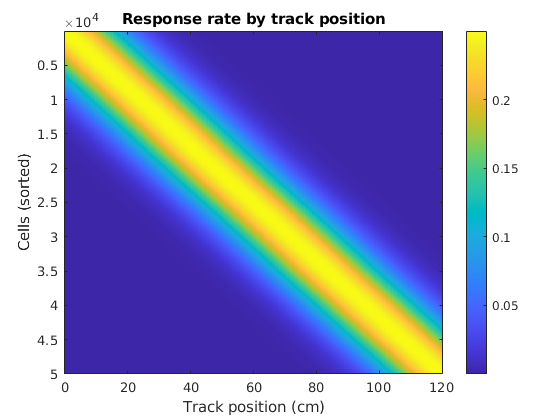

figure;
x_examples = 0:0.5:120;
imagesc(x_examples, 1:n_cells, rate_func(x_examples));
colorbar;
xlabel 'Track position (cm)'
ylabel 'Cells (sorted)'
title 'Response rate by track position'

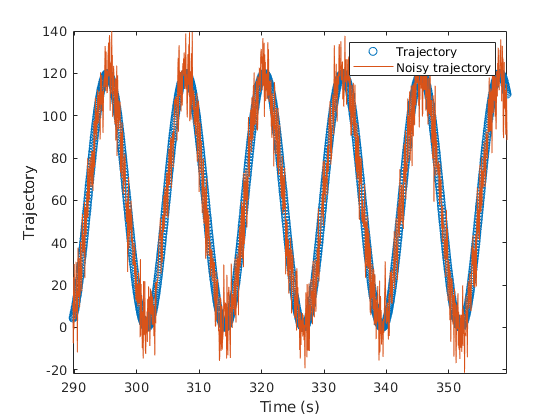

dt = seconds(1/20);
sess_time = hours(0.5);
max_v = 30; %cm/s

t = seconds(seconds(0):dt:sess_time); %s
x_traj = track_len .* sin(max_v./track_len .* t).^2;

noise_sigma = 10; %cm
input_noise = noise_sigma*randn(size(x_traj));

figure;
plot(t, x_traj, 'o');
hold on;
plot(t, x_traj + input_noise);
xlabel 'Time (s)'
ylabel 'Trajectory'
legend 'Trajectory' 'Noisy trajectory'

xlim([289.8 359.3])
ylim([-22 140])

response_type = "poisson";
switch response_type
    case "poisson"
        response_sample = @(x) poissrnd(rate_func(x));
        alg = fastpnb;
    case "gaussian"
        output_noise = 0.25;
        response_sample = @(x) rate_func(x) + output_noise.*randn(n_cells, numel(x));
        alg = fastdlda;
end

X_noise = response_sample(x_traj + input_noise);

figure;
imagesc(t, 1:n_cells, X_noise);

xlim([-0.0 58.8])

dt_opts = DecodeTensor.default_opt;
[~,~,tr_s,tr_e,tr_dir,tr_bins,~] = DecodeTensor.new_sel(position, dt_opts);

data_tensor = DecodeTensor.construct_tensor(X_noise.', tr_bins, dt_opts.n_bins, tr_s, tr_e);
position = [x_traj(:), 0*x_traj(:)];

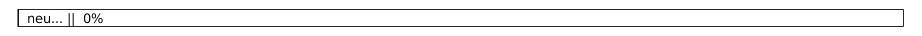


approx_samp = 50;
n_neu = unique(round(logspace(0,log10(n_cells),approx_samp)));

n_reps = 80;

%progressbar('reps...', 'neu...');
progressbar('neu...');

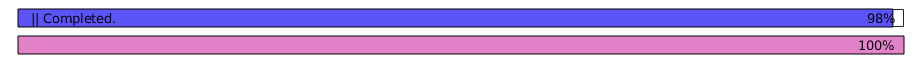

[mse, mse_sh] = deal(zeros(n_reps, numel(n_neu)));

for r_ix = 1:n_reps
    for n_ix = 1:numel(n_neu)

        err_res = DecodeTensor.decode_all(data_tensor,...
            tr_dir, 6, alg, n_neu(n_ix), []);

        mse(r_ix, n_ix) = err_res.MSE.unshuffled;
        mse_sh(r_ix, n_ix) = err_res.MSE.shuffled;

        progressbar([],n_ix/numel(n_neu));
    end
    progressbar(r_ix/n_reps, []);
    %progressbar((numel(n_neu) - n_ix + 1)/numel(n_neu));
end

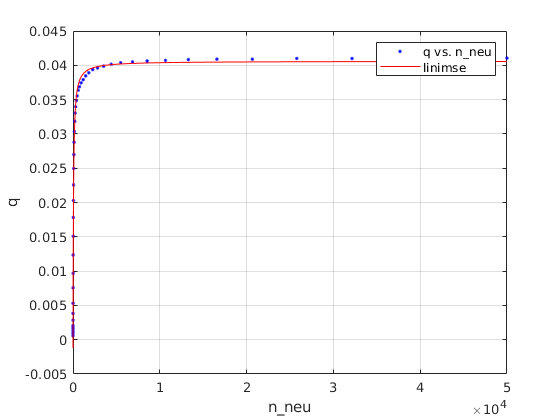

fr_real =      General model:
     fr_real(n) = I_0*n / (1 + n/N) + c
     Coefficients (with 95% confidence bounds):
       I_0 =   0.0008014  (0.0007376, 0.0008653)
       N =       53.16  (49.41, 56.92)
       c =   -0.002004  (-0.002697, -0.00131)

fit_func = @createFit_intercept;

fr_real = fit_func(n_neu, mean(1./mse))

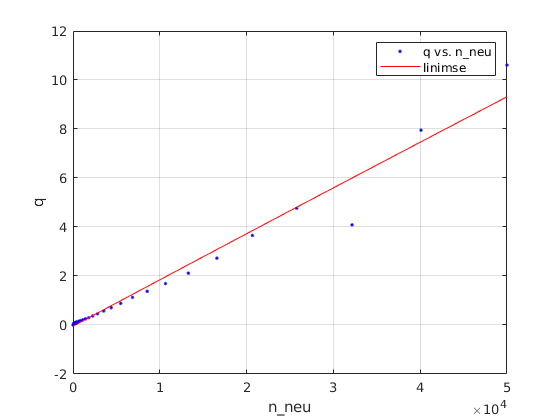

fr_shuf =      General model:
     fr_shuf(n) = I_0*n / (1 + n/N) + c
     Coefficients (with 95% confidence bounds):
       I_0 =   0.0001896  (0.0001583, 0.0002209)
       N =   3.932e+06  (-5.867e+07, 6.654e+07)
       c =    -0.04642  (-0.1768, 0.08401)

fr_shuf = fit_func(n_neu, mean(1./mse_sh))

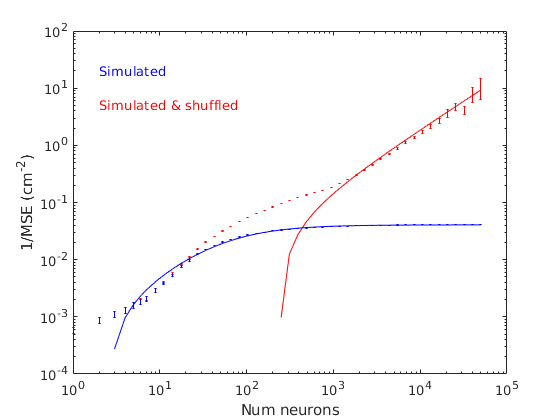

figure;
ep(n_neu, 1./mse_sh, 'r.'); hold on;
plot(n_neu, fr_shuf(n_neu), 'r');

ep(n_neu, 1./mse, 'b.'); 
plot(n_neu, fr_real(n_neu), 'b');

xlabel 'Num neurons'
ylabel '1/MSE (cm^{-2})'
set(gca, 'XScale', 'log');
set(gca, 'YScale', 'log');

text(2, 20, 'Simulated', 'Color', 'b');
text(2, 5, 'Simulated & shuffled', 'Color', 'r');

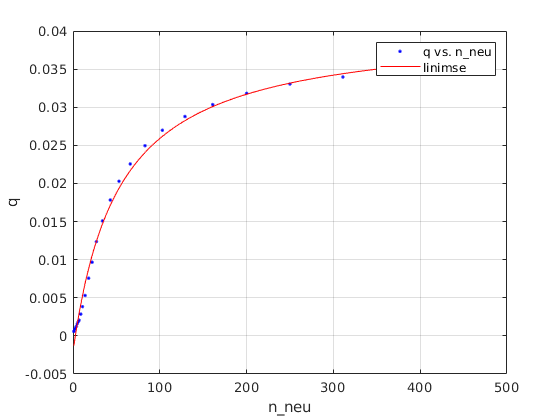

fr_real_short =      General model:
     fr_real_short(n) = I_0*n / (1 + n/N) + c
     Coefficients (with 95% confidence bounds):
       I_0 =   0.0008154  (0.0007072, 0.0009236)
       N =       52.27  (44.8, 59.75)
       c =   -0.002091  (-0.003048, -0.001134)

N_short = 500;

short_filt = n_neu <= N_short;
n_neu_short = n_neu(short_filt);

imse_short = mean(1./mse);
imse_short = imse_short(short_filt);

imse_sh_short = mean(1./mse_sh);
imse_sh_short = imse_sh_short(short_filt);

fr_real_short = fit_func(n_neu_short, imse_short)

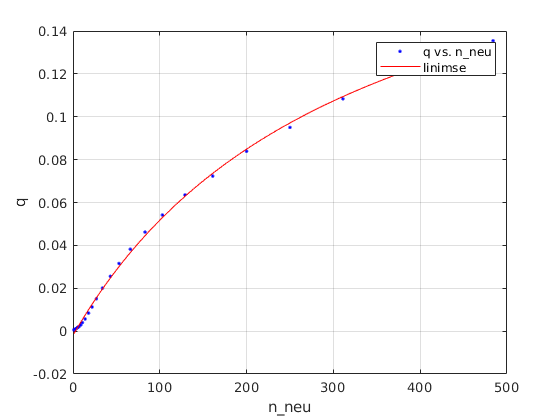

fr_shuf_short =      General model:
     fr_shuf_short(n) = I_0*n / (1 + n/N) + c
     Coefficients (with 95% confidence bounds):
       I_0 =   0.0007039  (0.000671, 0.0007368)
       N =         322  (294.5, 349.4)
       c =   -0.001948  (-0.002852, -0.001043)

fr_shuf_short = fit_func(n_neu_short, imse_sh_short)

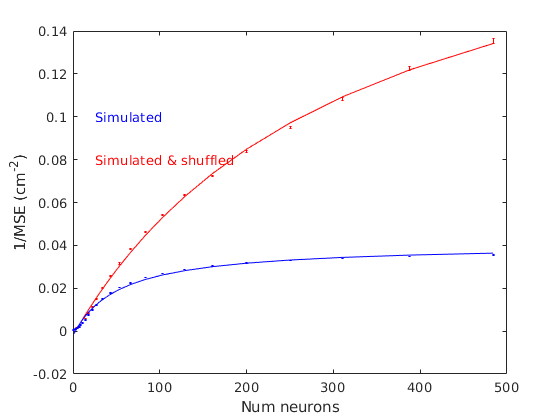

figure;
ep(n_neu_short, 1./mse_sh(:,short_filt), 'r.'); hold on;
plot(n_neu_short, fr_shuf_short(n_neu_short), 'r');

ep(n_neu_short, 1./mse(:,short_filt), 'b.');
plot(n_neu_short, fr_real_short(n_neu_short), 'b');

xlabel 'Num neurons'
ylabel '1/MSE (cm^{-2})'
%set(gca, 'XScale', 'log');
%set(gca, 'YScale', 'log');

text(25, 0.1, 'Simulated', 'Color', 'b');
text(25, 0.08, 'Simulated & shuffled', 'Color', 'r');

figure;

hold on;
plot(n_neu, fr_real(n_neu), 'g');
plot(n_neu_short, fr_real_short(n_neu_short), 'b');
ep(n_neu, 1./mse, 'k.');

set(gca, 'XScale', 'log');
set(gca, 'YScale', 'log');
xlabel 'Number of neurons'

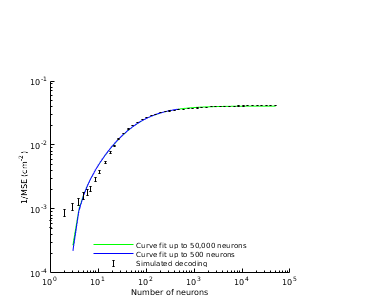

ylabel '1/MSE (cm^{-2})'
legend 'Curve fit up to 50,000 neurons' 'Curve fit up to 500 neurons' 'Simulated decoding'
legend Location best
legend boxoff
figure_format([5 4]/2);
Utils.printto('fitting_stability', 'IMSE_fits.pdf');

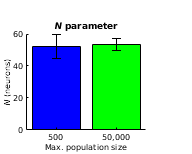


figure;
eb(categorical({'500'}), fr_real_short, 'b');
hold on;
eb(categorical({'50,000'}), fr_real, 'g');
title '{\itN} parameter'
xlabel 'Max. population size'
ylabel '{\itN} (neurons)'
figure_format([2.5 2]/2);
Utils.printto('fitting_stability', 'N_fits.pdf');

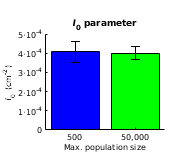


figure;
ebI(categorical({'500'}), fr_real_short, 'b');
hold on;
ebI(categorical({'50,000'}), fr_real, 'g');
title '{\itI}_0 parameter'
xlabel 'Max. population size'
ylabel '{\itI}_0 (cm^{-2})'
Utils.fix_exponent(gca, 'y', 0);
figure_format([2.5 2]/2);
Utils.printto('fitting_stability', 'I0_fits.pdf');

approx_samp = 20;
n_neu_dp = unique(round(logspace(log10(2),log10(n_cells),approx_samp)));

n_reps = 16;

%progressbar('reps...', 'neu...');
progressbar('neu...');

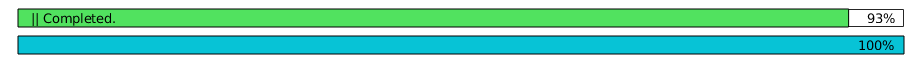

[dp2, dp2_shuf] = deal(zeros(n_reps, numel(n_neu_dp)));

for r_ix = 1:n_reps
    for n_ix = 1:numel(n_neu_dp)
    
        %err_res = DecodeTensor.decode_all(data_tensor,...
        %    tr_dir, 6, alg, n_neu(n_ix), []);

        [nv, nv_s, ~, m2, m2_s, ~, ~] = DecodeTensor.adjacent_decoder_noise(data_tensor,...
            tr_dir, n_neu_dp(n_ix), []);
        
        my_dp2 = m2./(nv + eps);
        my_dp2_shuf = m2_s ./ (nv_s + eps);
        
        dp2(r_ix, n_ix) = mean(my_dp2(:));
        dp2_shuf(r_ix, n_ix) = mean(my_dp2_shuf(:));
        
        %mse(r_ix, n_ix) = err_res.MSE.unshuffled;
        %mse_sh(r_ix, n_ix) = err_res.MSE.shuffled;

        progressbar([],n_ix/numel(n_neu_dp));
    end
    progressbar(r_ix/n_reps, []);
    %progressbar((numel(n_neu_dp) - n_ix + 1)/numel(n_neu_dp));
end

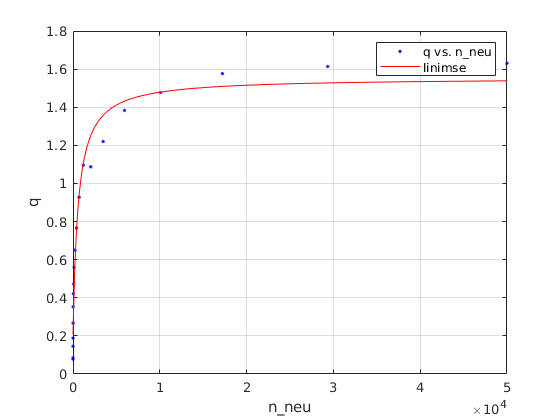

fr_real =      General model:
     fr_real(n) = I_0*n / (1 + n/N) + c
     Coefficients (with 95% confidence bounds):
       I_0 =    0.002283  (0.001383, 0.003183)
       N =       591.8  (356, 827.5)
       c =      0.2031  (0.1239, 0.2823)

fit_func = @createFit_intercept;

fr_real = fit_func(n_neu_dp, mean(dp2,1))

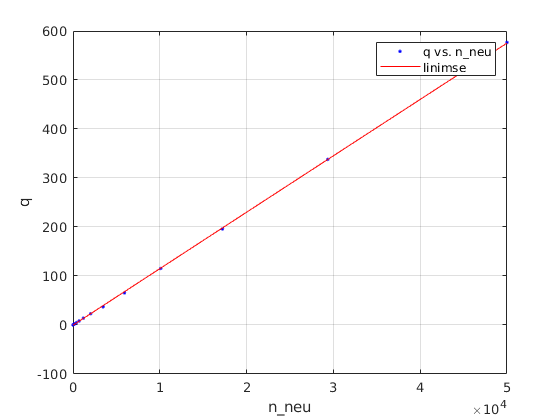

fr_shuf =      General model:
     fr_shuf(n) = I_0*n / (1 + n/N) + c
     Coefficients (with 95% confidence bounds):
       I_0 =     0.01154  (0.01139, 0.01168)
       N =   2.713e+07  (-1.805e+08, 2.347e+08)
       c =     -0.3458  (-0.9985, 0.3068)

fr_shuf = fit_func(n_neu_dp, mean(dp2_shuf,1))

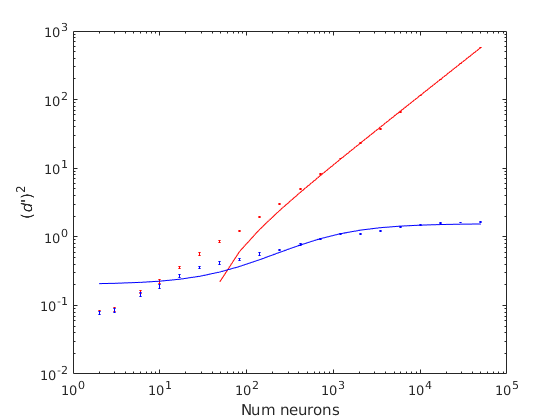


figure;
ep(n_neu_dp, dp2_shuf, 'r.'); hold on;
plot(n_neu_dp, fr_shuf(n_neu_dp), 'r');

ep(n_neu_dp, dp2, 'b.'); 
plot(n_neu_dp, fr_real(n_neu_dp), 'b');

xlabel 'Num neurons'
ylabel '({\itd}'')^2'

set(gca, 'XScale', 'log');
set(gca, 'YScale', 'log');

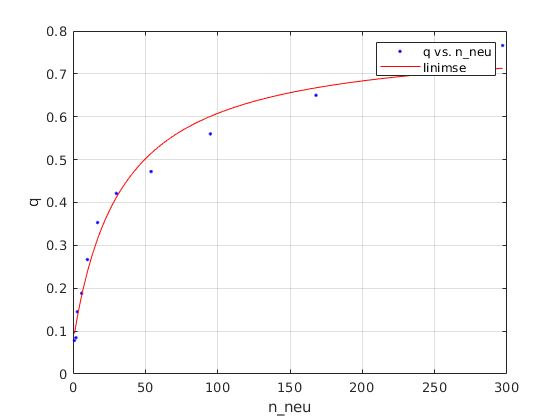

fr_real_short =      General model:
     fr_real_short(n) = I_0*n / (1 + n/N) + c
     Coefficients (with 95% confidence bounds):
       I_0 =     0.02156  (0.01101, 0.0321)
       N =       32.97  (15.6, 50.35)
       c =      0.0734  (0.01634, 0.1305)

N_short = 500;

filt_short = n_neu_dp < N_short;
n_neu_dp_short = n_neu(filt_short);
mdp2_short = mean(dp2,1);
mdp2_short = mdp2_short(filt_short);

mdp2_shuf_short = mean(dp2_shuf,1);
mdp2_shuf_short = mdp2_shuf_short(filt_short);

fr_real_short = fit_func(n_neu_dp_short, mdp2_short)

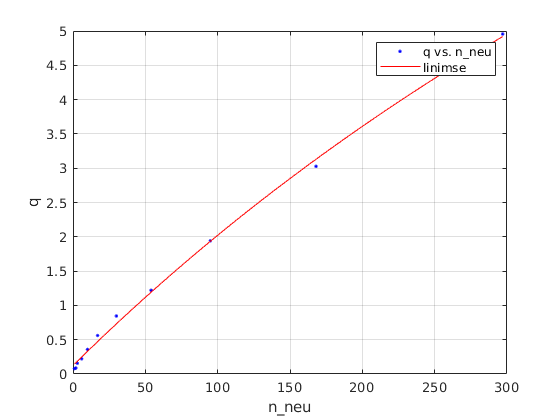

fr_shuf_short =      General model:
     fr_shuf_short(n) = I_0*n / (1 + n/N) + c
     Coefficients (with 95% confidence bounds):
       I_0 =     0.02084  (0.01819, 0.02349)
       N =        1021  (418.6, 1624)
       c =      0.1239  (0.04602, 0.2017)

fr_shuf_short = fit_func(n_neu_dp_short, mdp2_shuf_short)

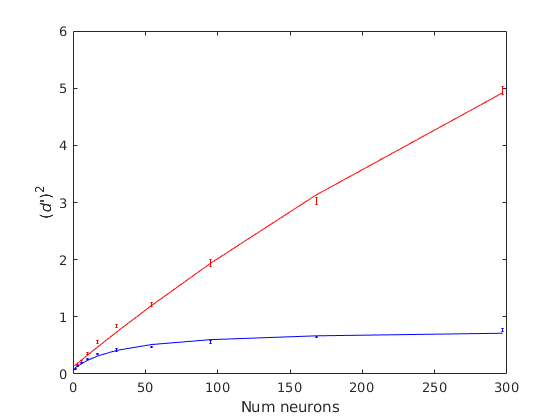


figure;
ep(n_neu_dp_short, dp2_shuf(:, filt_short), 'r.'); hold on;
plot(n_neu_dp_short, fr_shuf_short(n_neu_dp_short), 'r');

ep(n_neu_dp_short, dp2(:, filt_short), 'b.'); 
plot(n_neu_dp_short, fr_real_short(n_neu_dp_short), 'b');

xlabel 'Num neurons'
ylabel '({\itd}'')^2'

function b = eb(ix, sf, c)
    ci = confint(sf);
    ci = ci(:,2);
    e = num2cell(ci - sf.N);
    b = bar(ix, sf.N, c); hold on;
    errorbar(ix, sf.N, e{:}, 'k');
end

function b = ebI(ix, sf, c)
    ci = confint(sf);
    ci = ci(:,1);
    e = num2cell(ci - sf.I_0);
    b = bar(ix, sf.I_0, c); hold on;
    errorbar(ix, sf.I_0, e{:}, 'k');
end

function ep(n, m, varargin)
m_mean = mean(m, 1);
samples = size(m, 1);
m_std = std(m, [], 1);
m_sem = m_std ./ sqrt(samples);
errorbar(n, m_mean, m_sem.*1.96, varargin{:},...
    "CapSize", 1, "Marker", "none", 'LineStyle', "none");
end